% Test 1 A Measurements
Input_Ref = flip([80 70 60 50 40 30 20 10 0]);
Input_Resistance = flip([130.765 127.035 123.222 119.42 115.585 111.722 107.863 103.952 100.084]);
Calculated_Temperature = 0.00111611.*Input_Resistance.^2 + 2.32652102.*Input_Resistance - 243.7648049;
Measured_Temperature = flip([78.8, 69.2, 59.4, 49.7, 39.9, 30.1, 20.4, 10.6, 0.9]);



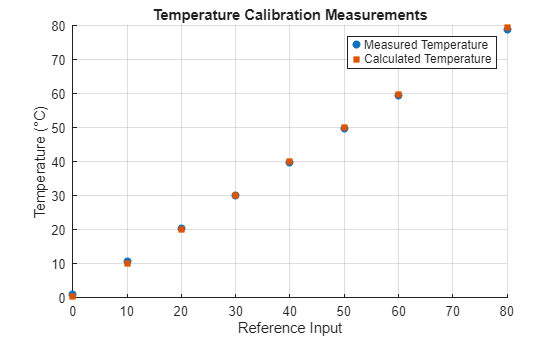


figure

scatter(Input_Ref, Measured_Temperature, 'filled')
hold on

p_Measured = polyfit(Input_Ref, Measured_Temperature, 1);
y_Measured = polyval(p_Measured, Input_Ref);
%plot(Input_Ref, y_Measured, 'LineWidth', 2)

scatter(Input_Ref, Calculated_Temperature,'filled', 'square')
p_Calculated = polyfit(Input_Ref, Calculated_Temperature, 1);
Y_Calculated = polyval(p_Calculated, Input_Ref);
%plot(Input_Ref, Y_Calculated, 'LineWidth', 2)
xlabel('Reference Input')
ylabel('Temperature (°C)')
% legend('Measured Temperature', 'Linear Fit (Measured)', 'Calculated Temperature', 'Linear Fit (Calculated)')
legend('Measured Temperature', 'Calculated Temperature')
title('Temperature Calibration Measurements')
grid on
hold off

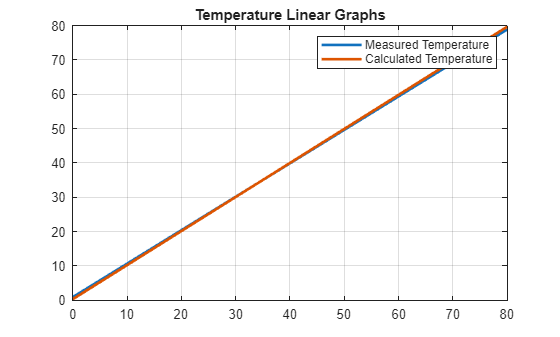


figure

plot(Input_Ref, y_Measured, 'LineWidth', 2)
hold on
plot(Input_Ref, Y_Calculated, 'LineWidth', 2)
legend('Measured Temperature', 'Calculated Temperature')
title('Temperature Linear Graphs')
grid on
hold off


m_Measured = p_Measured(1);
m_Calculated = p_Calculated(1);
c_Measured = p_Measured(2);
c_Calculated = p_Calculated(2);

Temp_Real = @(Measured_Value)(m_Calculated * ((Measured_Value - c_Measured)/m_Measured) + c_Calculated)

Temp_Real = function_handle with value:
    @(Measured_Value)(m_Calculated*((Measured_Value-c_Measured)/m_Measured)+c_Calculated)



Temp_50 = Temp_Real(50);
Answer = Temp_50 - Calculated_Temperature(6);

% Test 1 B Measurements

%{
    Sensor 1 -> 2873C395000000D3
    Sensor 2 -> 2821F096000000D1
%}

Reference_Temperature = [43.8 41.9 40 38.3 36.6 35.2 34 32.8 31.7 30.7 29.8 29.1 28.4 27.9 27.2 26.7 26.2 25.9 15.6 15 14.4 13.7 12.9 12 10.6];
Real_Temperature = Temp_Real(Reference_Temperature);
Sensor_1 = [40.52 38.46 37.31 35.06 33.6 32.31 31.17 30.14 29.12 28.32 27.55 26.88 26.38 25.83 25.31 24.89 24.54 24.16 16.26 15.88 15.41 14.88 14.31 13.68 13];
Sensor_2 = [40.96 39.04 36.693 35.82 34.44 33.26 32.18 31.23 30.31 29.58 28.89 28.36 27.83 27.4 26.93 26.64 26.31 26.04 16.44 16.06 15.59 15.08 14.52 13.87 13.01];


p_1 = polyfit(Real_Temperature, Sensor_1, 1)

p_1 =     0.8095    3.8676


y_1 = polyval(p_1, Real_Temperature);

p_2 = polyfit(Real_Temperature, Sensor_2, 1)

p_2 =     0.8271    4.2511


y_2 = polyval(p_2, Real_Temperature);

Real_Temp_1 = @(Temp)((Temp - p_1(2))/p_1(1))

Real_Temp_1 = function_handle with value:
    @(Temp)((Temp-p_1(2))/p_1(1))


Real_Temp_2 = @(Temp)((Temp - p_2(2))/p_2(1))

Real_Temp_2 = function_handle with value:
    @(Temp)((Temp-p_2(2))/p_2(1))


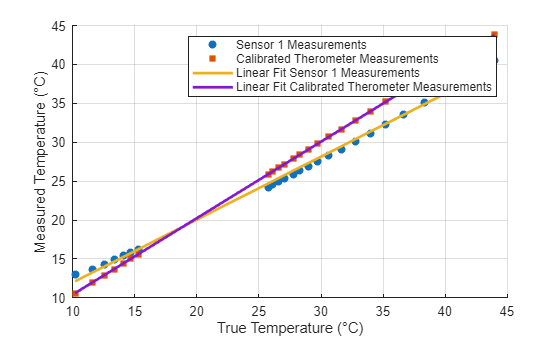




figure

scatter(Real_Temperature, Sensor_1, 'filled')
hold on
scatter(Real_Temperature, Reference_Temperature, 'filled', 'square')
plot(Real_Temperature, y_1, 'LineWidth', 2)
plot(Real_Temperature, Reference_Temperature, 'LineWidth',2)
xlabel('True Temperature (°C)');
ylabel('Measured Temperature (°C)');
legend('Sensor 1 Measurements', 'Calibrated Therometer Measurements', 'Linear Fit Sensor 1 Measurements', 'Linear Fit Calibrated Therometer Measurements');
grid on
hold off

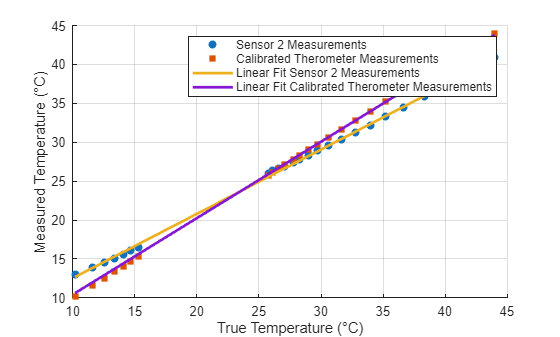



figure

scatter(Real_Temperature, Sensor_2, 'filled')
hold on
scatter(Real_Temperature, Real_Temperature, 'filled', 'square')
plot(Real_Temperature, y_2, 'LineWidth', 2);
plot(Real_Temperature, Reference_Temperature, 'LineWidth',2)
xlabel('True Temperature (°C)');
ylabel('Measured Temperature (°C)');
legend('Sensor 2 Measurements', 'Calibrated Therometer Measurements', 'Linear Fit Sensor 2 Measurements', 'Linear Fit Calibrated Therometer Measurements');
grid on
hold off

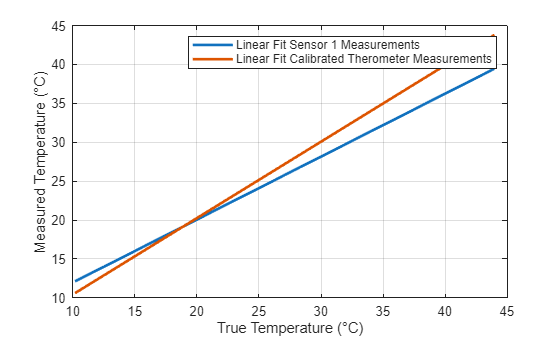



figure

plot(Real_Temperature, y_1, 'LineWidth', 2)
hold on
plot(Real_Temperature, Reference_Temperature, 'LineWidth',2)
xlabel('True Temperature (°C)');
ylabel('Measured Temperature (°C)');
legend('Linear Fit Sensor 1 Measurements', 'Linear Fit Calibrated Therometer Measurements')
grid on
hold off

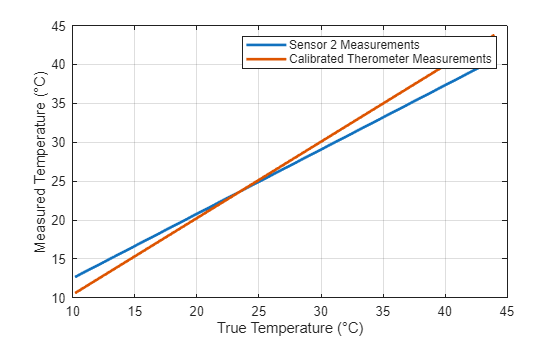



figure

plot(Real_Temperature, y_2, 'LineWidth', 2);
hold on
plot(Real_Temperature, Reference_Temperature, 'LineWidth',2)
xlabel('True Temperature (°C)');
ylabel('Measured Temperature (°C)');
legend('Sensor 2 Measurements', 'Calibrated Therometer Measurements')
grid on
hold off

% Test 2
Time = [0 10 20 30 40 50 60 70 80 90 100 110];
Time_Measurements = [23.40 26.77 25.13 24.99 25.04 25.14 28.34 29.19 29.72 28.91 28.27 26.51];
Volume = 473/(1000)^3;
mass = Volume*1.204;
c = 1005; %J/(kg*K)

Q_dot = @(Temp_Diff)(c*mass*Temp_Diff/(10*60))

Q_dot = function_handle with value:
    @(Temp_Diff)(c*mass*Temp_Diff/(10*60))


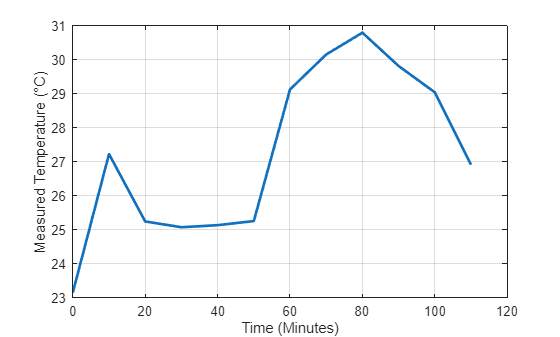


True_Time_Measurements = Real_Temp_2(Time_Measurements);

Difference_Measurements = diff(True_Time_Measurements);
Max_Diff = max(Difference_Measurements);
Min_Diff = min(Difference_Measurements);
Avg_Diff = mean(Difference_Measurements);


figure
plot(Time, True_Time_Measurements, 'LineWidth',2)
hold on 
xlabel('Time (Minutes)');
ylabel('Measured Temperature (°C)');
grid on
hold off



Q_dot_values = Q_dot(Difference_Measurements);


Q_max = Q_dot(Max_Diff)

Q_max = 3.8865e-06

Q_avg =  Q_dot(Avg_Diff)

Q_avg = 3.2606e-07

Q_min = Q_dot(Min_Diff)

Q_min = -2.0298e-06